% Parâmetros gerais
Fs = 100e3;          % Frequência de amostragem (100 kHz)
duration = 0.1;      % Duração do sinal (0.1 segundos)
t = 0:1/Fs:duration; % Vetor de tempo

% Sinal de entrada simulado (saída do Buck)
V_buck = 12 * sin(2*pi*1e3*t) + 0.5*randn(size(t)); % Senoide de 1 kHz com ruído
% Parâmetros do filtro Sallen-Key
R1_filtro = 1e3;  % 1 kΩ
R2_filtro = 1e3;  % 1 kΩ
C1_filtro = 100e-9; % 100 nF
C2_filtro = 100e-9; % 100 nF

% Função de transferência do filtro
s = tf('s');
num = 1 / (R1_filtro * C1_filtro * R2_filtro * C2_filtro);
den = [1, (1/(R2_filtro*C1_filtro) + (1/(R1_filtro*C1_filtro)), 1/(R1_filtro*C1_filtro*R2_filtro*C2_filtro)];

Invalid expression. When calling a function or indexing a variable, use parentheses. Otherwise, check for mismatched delimiters.

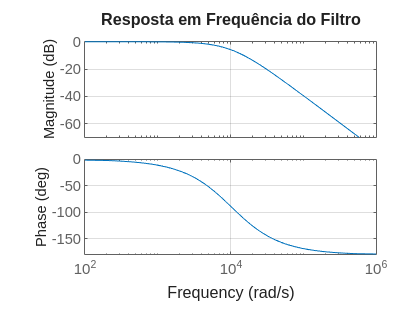

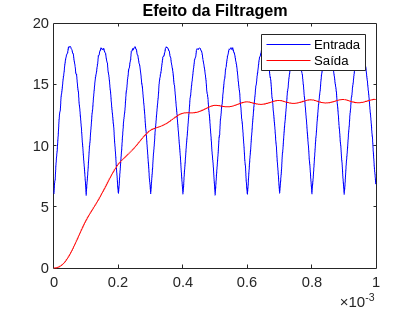

G_filtro = tf(num, den);

% Simulação da resposta do filtro
V_filtrado = lsim(G_filtro, V_subtrator, t);